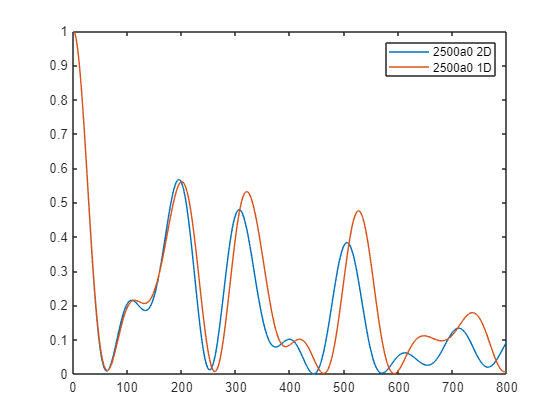

add_list = [(500:500:2500)]*a0;
for add = add_list/a0
load(['Data\D4_2D_Tstep200_Tnow798_U050_add',num2str(add)]);
task2D = obj;
load(['Data\D4_1D_Tstep200_Tnow798_U050_add',num2str(add)]);
task1D = obj;
NmaxP = 2;

MomentumDensity2D = Get_momentumDesity_2D( ...
        task2D.history.MomentumDensity,NmaxP+1,1:NmaxP*2+1);
MomentumDensity2D = MomentumDensity2D ...
    ./max(MomentumDensity2D(:));
% MomentumDensity2D = MomentumDensity2D./sum(MomentumDensity2D,2);
MomentumDensity1D = task1D.history.MomentumDensity;

trange = (1:task2D.history.steps_ext)*task2D.history.tstep*task2D.history.steps_int*task2D.Tscale;

plot(trange*10^6, MomentumDensity2D(:,NmaxP+1)' ...
    ,'DisplayName',[num2str(add),'a0 2D'])
hold on 
plot(trange*10^6, MomentumDensity1D(:,NmaxP+1)' ...
    ,'DisplayName',[num2str(add),'a0 1D'])
hold off
legend
end